% PHYS 434
% LAB 6
% Jin Kyoung Lee

% Creating background data: Poisson distribution with lambda=100
lambda = 100;
background = makedist("Poisson", "lambda", lambda);

## Problem 1

% Determine where the 5 sigma sensitivity threshold of the background is.
bg5Sigma = [1/3.5e6, 1-1/3.5e6];
threshold = icdf(background,bg5Sigma)

threshold =     54   154


% The 5 sigma sensitivity threshold of the background is 54 and 154

## Problem 2

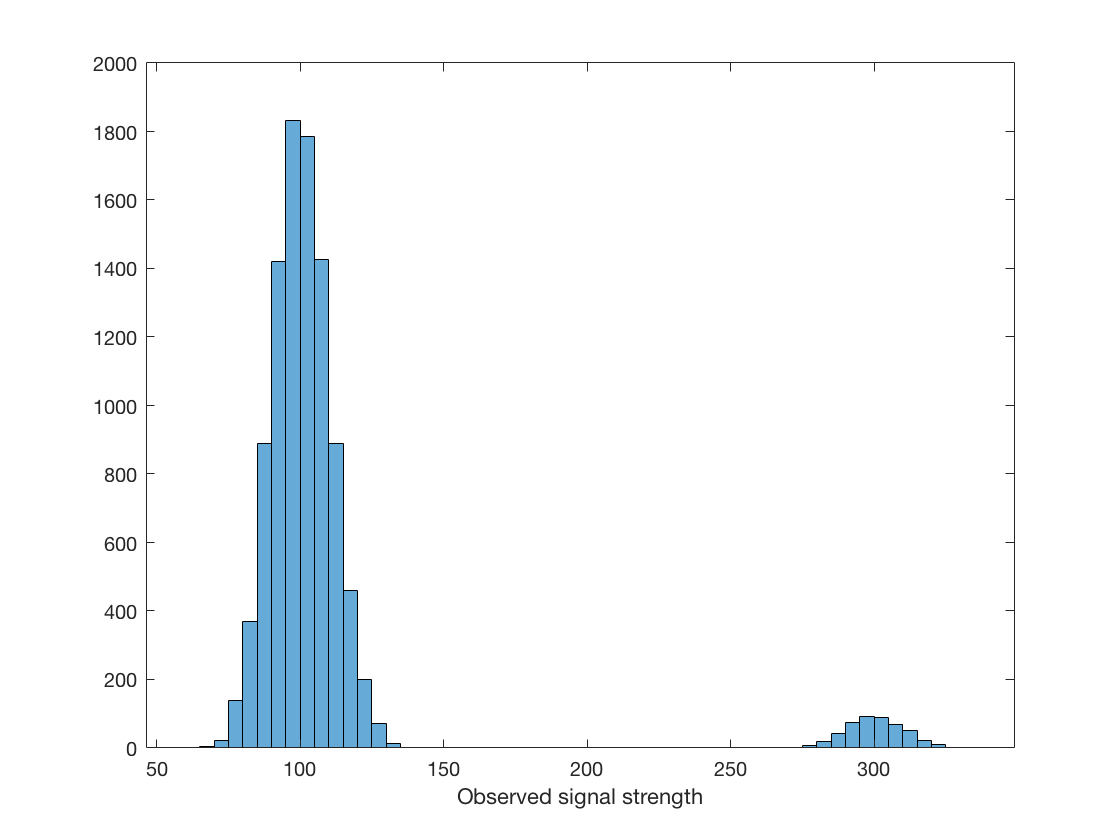

% Creating a set of injected (simulated) signals of a single strength
size = 10000;
noise = poissrnd(100,1,size);
signal = zeros(1,size);
signal(randi(numel(signal),[1,500])) = 200;
obssignal = noise + signal;

histogram(obssignal,'DisplayStyle','bar')
xlabel('Observed signal strength')

% a) The histogram has similar shape of Gaussian distribution, and this
% shows that, even though we inject signals of a single strength, the 
% observation gives range of measurement.

% b) It is observed that the observed signal is stronger than the true 
% injected signal.

## Problem 3

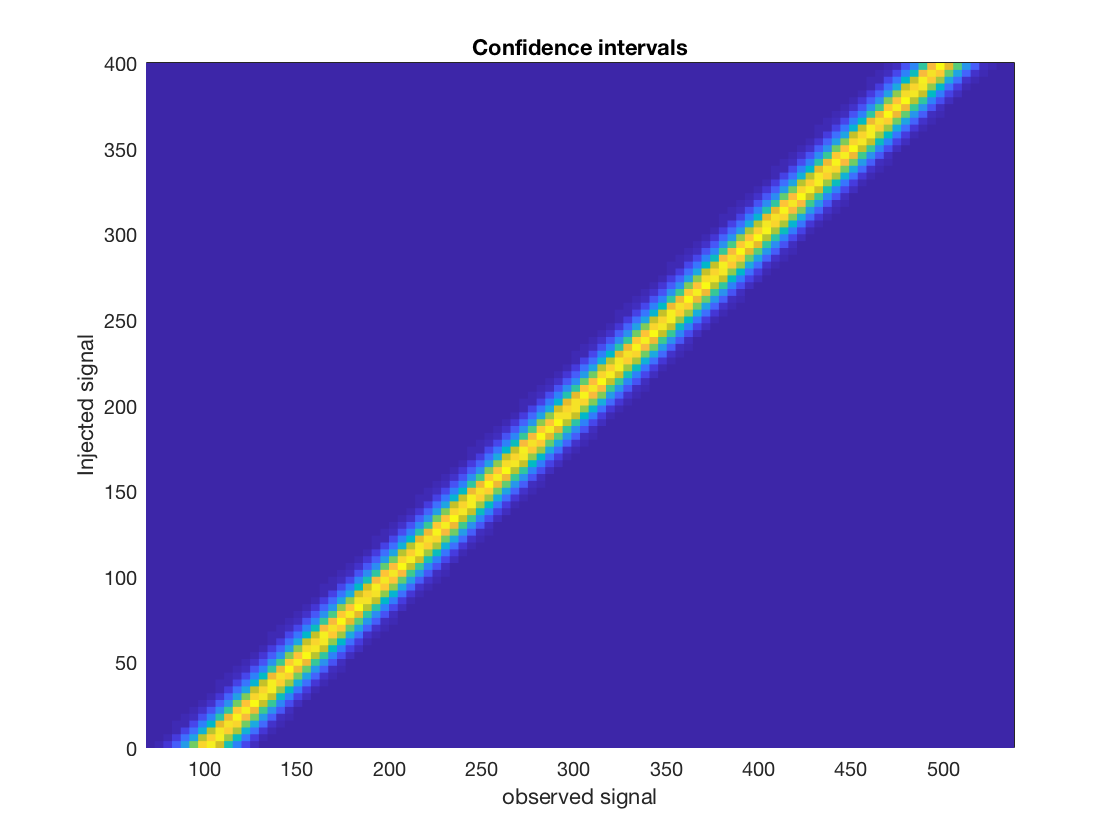

% a) We are simulating that if we are injecting a range of signal strength,
% what value of signal will be observed.

size = 1000;
noise = poissrnd(100,1,size);
signalstrength = linspace(0,400,size);
[scratch, signal] = meshgrid(signalstrength);
obssignal = noise + signal;

figure()
histogram2(obssignal,signal,100,'DisplayStyle','tile','ShowEmptyBins','on');
ylabel("Injected signal")
xlabel("observed signal")
title("Confidence intervals")

% b)
figure()
index = 501;
signal(index)

ans = 200.2002

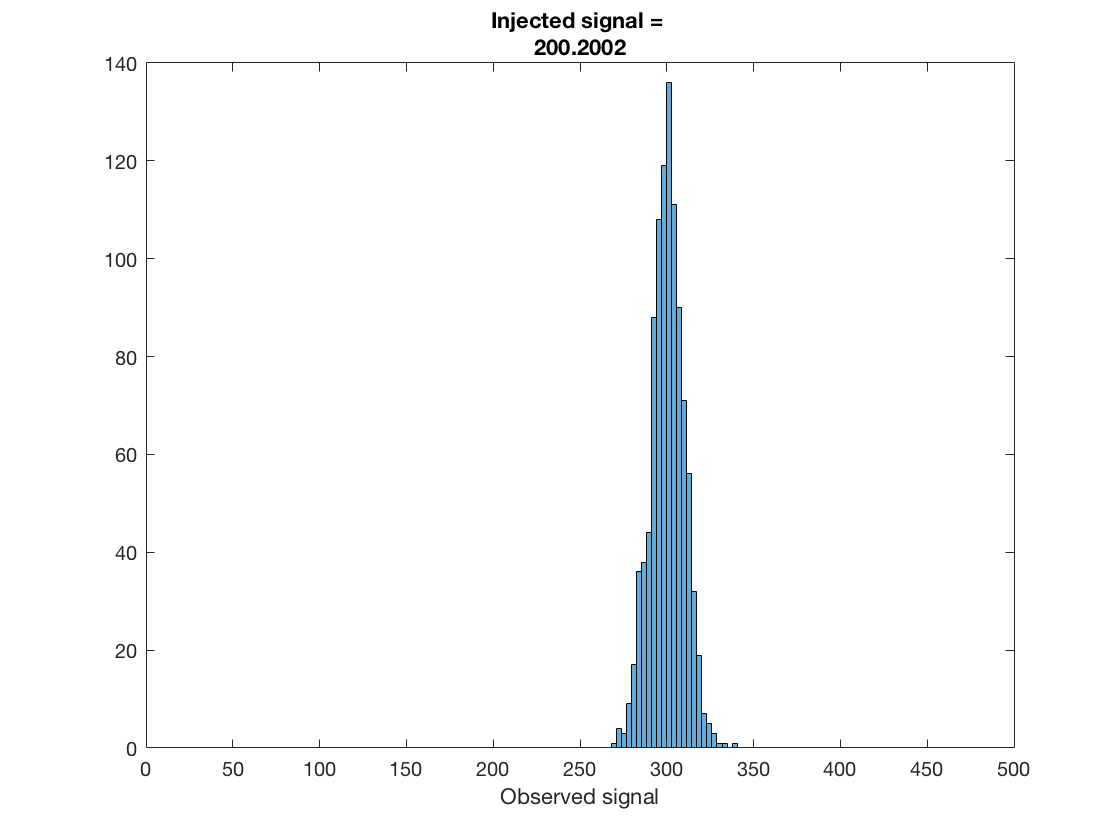

histogram(obssignal(index,:),25,'DisplayStyle','bar')
xlim([0,500]);
title(["Injected signal = ", num2str(signal(index))])
xlabel("Observed signal")

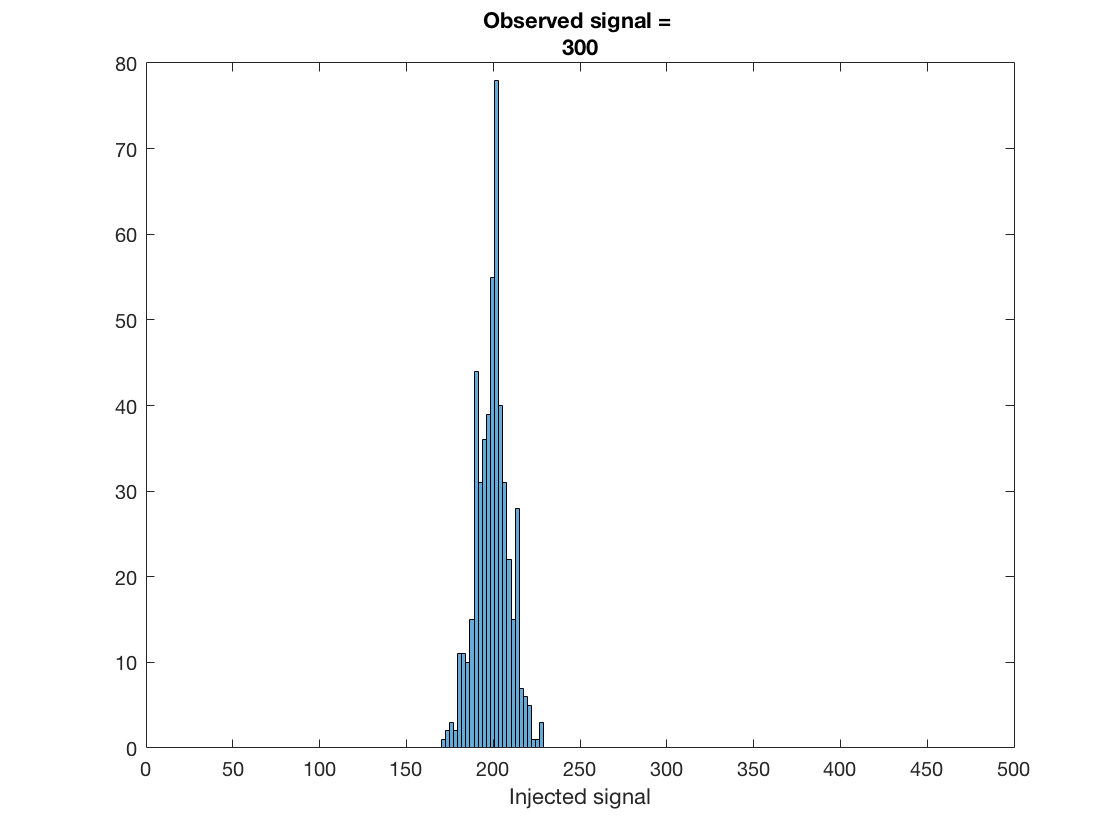

% c)
observationProb3 = 300;
injected = signal(abs(obssignal - observationProb3)<0.05);
histogram(injected,25,'DisplayStyle','bar')
xlim([0,500]);
title(["Observed signal = ", num2str(observationProb3)])
xlabel("Injected signal") 

% The histogram shows the probability of measureing observed signal, and it
% is giving the range of true value of the observation.

% d) 1 sigma = 67%; + or - 33.5% from 200:
% Therefore, 1 sigma uncertainty on the true signal strength is
% approsimately 190 < Z < 210

## Problem 4

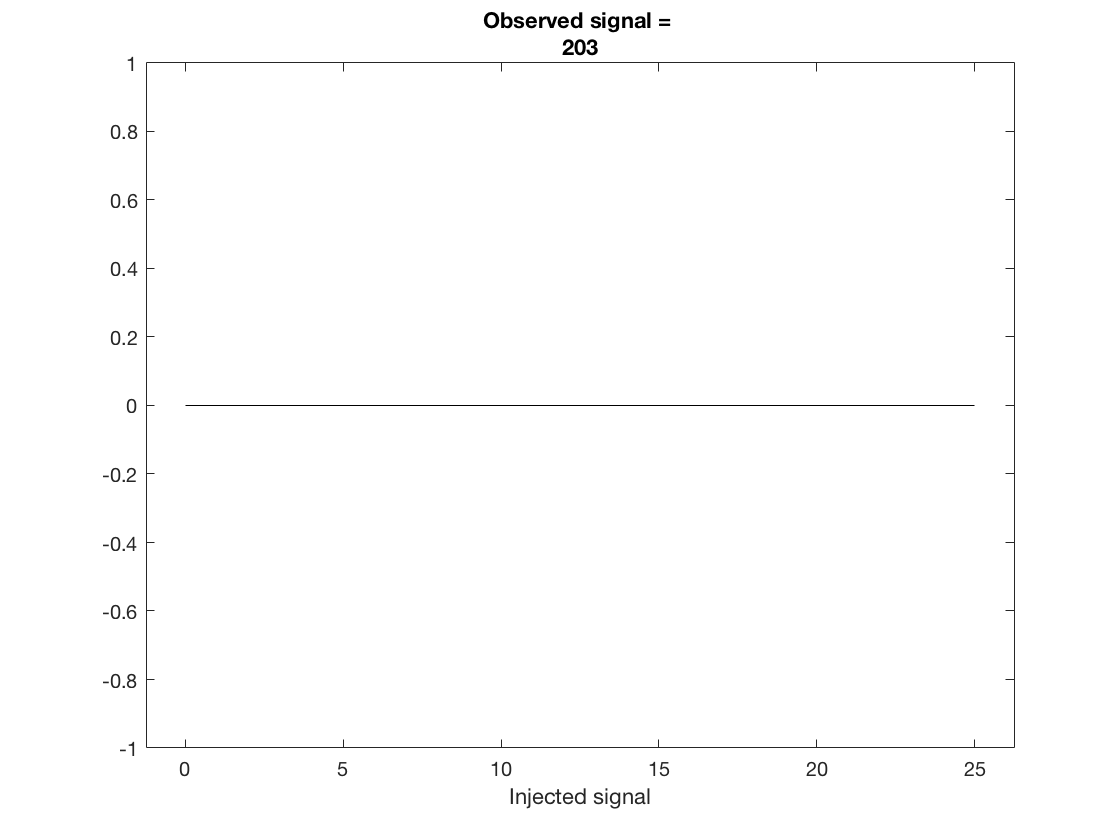

% a)
observationProb4 = 203; % Choosing values between 190 and 210
injected = signal(abs(obssignal - observationProb4)<0.05);
histogram(injected,25,'DisplayStyle','bar')
title(["Observed signal = ", num2str(observationProb4)])
xlabel("Injected signal") 

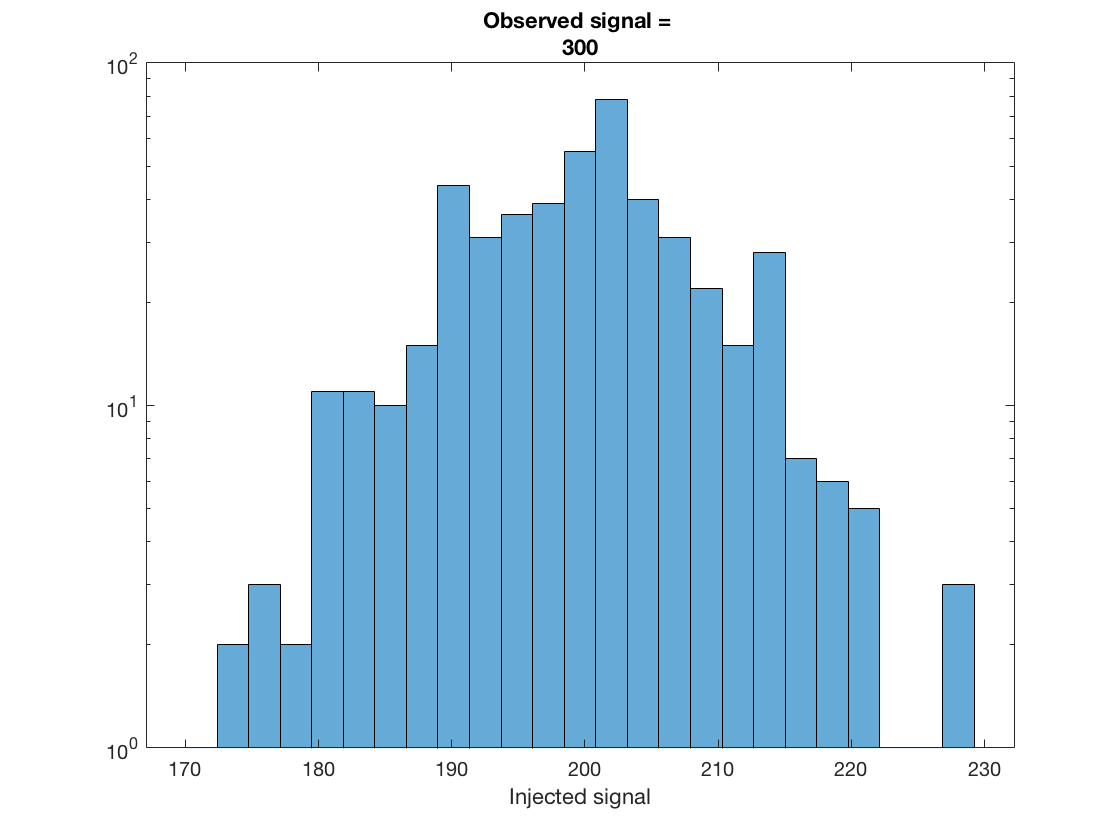

% b) The true signal pdf() extend to zero means that our candidate signal
% is weak to say that there is a signal ditection.

% c) 95% confidence: 2 sigma
observation = 300;
injected = signal(abs(obssignal - observation)<0.05); 
histogram(injected,25,'DisplayStyle','bar')
title(["Observed signal = ", num2str(observation)])
xlabel("Injected signal") 

% 95% confidence upper bound will be approximately 220